# Problèmatique

## Calculs

warning('off','all')

A = [-0.018223 -0.088571 -9.78  0.0000;
     -0.003038 -1.256300  0.00  1.0000;
      0.000000  0.000000  0.00  1.0000;
      0.061700   -28.075  0.00 -4.5937];
B = [0.00  1.1962;
     0.00 -0.0012;
     0.00  0.0000;
     7.84 -4.0500];
C = [1  00.000  00.000 00.000;
     0  57.296  00.000 00.000;
     0  00.000  57.296 00.000;
     0  00.000  00.000 57.296;
     0 -57.296 -57.296 00.000];
D = [0 0;
     0 0;
     0 0;
     0 0;
     0 0];

%On sort les numérateur et dénominateurs des fonctions avec ABCD
%Num1 et Den1 sont par rapport à angle gouvernail (delta)
[Num1, Den1] = ss2tf(A,B,C,D,1);
%Num2 et Den2 sont par rapport à fraction pousser max (gamma)
[Num2, Den2] = ss2tf(A,B,C,D,2);

%5 premières fonctions est l'angle de gouvernail en fonction de [𝑣 𝛼 𝜃 𝑞 𝛾]
%6 à 10 sont la fraction de poussermax en fonction de [𝑣 𝛼 𝜃 𝑞 𝛾]
%𝑢 = [𝛿𝑐 𝑎𝑝𝑟𝑜𝑝]^T
%Y = [𝑣 𝛼 𝜃 𝑞 𝛾]^T



%On calcul le poids des pôles
[r1, p1, k1] = residue(Num1(1,:), Den1);
[r2, p2, k2] = residue(Num1(2,:), Den1);
[r3, p3, k3] = residue(Num1(3,:), Den1);
[r4, p4, k4] = residue(Num1(4,:), Den1);
[r5, p5, k5] = residue(Num1(5,:), Den1);
[r6, p6, k6] = residue(Num2(1,:), Den2);
[r7, p7, k7] = residue(Num2(2,:), Den2);
[r8, p8, k8] = residue(Num2(3,:), Den2);
[r9, p9, k9] = residue(Num2(4,:), Den2);
[r10, p10, k10] = residue(Num2(5,:), Den2);

%On calcul les poids
poids1 = abs(r1)./abs(real(p1));% 3 et 4 de beaucoup
poids2 = abs(r2)./abs(real(p2));%3 et 4 
poids3 = abs(r3)./abs(real(p3));%3 et 4 de beaucoup
poids4 = abs(r4)./abs(real(p4));%3 et 4
poids5 = abs(r5)./abs(real(p5));%3 et 4 de beaucoup
poids6 = abs(r6)./abs(real(p6));%3 et 4 de beaucoup
poids7 = abs(r7)./abs(real(p7));%3 et 4
poids8 = abs(r8)./abs(real(p8));%3 et 4 de beaucoup
poids9 = abs(r9)./abs(real(p9));%3 et 4
poids10 = abs(r10)./abs(real(p10));%3 et 4 de beaucoup

%On crée les nouvelles fonction de transfert avec les poids dominant
sys1_1 = tf([r1(3)], [1 -p1(3)]);
sys1_2 = tf([r1(4)], [1 -p1(4)]);

sys2_1 = tf([r2(3)], [1 -p2(3)]);
sys2_2 = tf([r2(4)], [1 -p2(4)]);

sys3_1 = tf([r3(3)], [1 -p3(3)]);
sys3_2 = tf([r3(4)], [1 -p3(4)]);

sys4_1 = tf([r4(3)], [1 -p4(3)]);
sys4_2 = tf([r4(4)], [1 -p4(4)]);

sys5_1 = tf([r5(3)], [1 -p5(3)]);
sys5_2 = tf([r5(4)], [1 -p5(4)]);

sys6_1 = tf([r6(3)], [1 -p6(3)]);
sys6_2 = tf([r6(4)], [1 -p6(4)]);

sys7_1 = tf([r7(3)], [1 -p7(3)]);
sys7_2 = tf([r7(4)], [1 -p7(4)]);

sys8_1 = tf([r8(3)], [1 -p8(3)]);
sys8_2 = tf([r8(4)], [1 -p8(4)]);

sys9_1 = tf([r9(3)], [1 -p9(3)]);
sys9_2 = tf([r9(4)], [1 -p9(4)]);

sys10_1 = tf([r10(3)], [1 -p10(3)]);
sys10_2 = tf([r10(4)], [1 -p10(4)]);

%Celle qui nous interesse le plus c'est F(2,1)
%On remplace les fonction de transfert par les nouvelles
FT = [sys1_1+sys1_2 sys2_1+sys2_2 sys3_1+sys3_2 sys4_1+sys4_2 sys5_1+sys5_2;
      sys6_1+sys6_2 sys7_1+sys7_2 sys8_1+sys8_2 sys9_1+sys9_2 sys10_1+sys10_2];

%On calcule les coefficient des fonctions de transfert
[num1, den1] = tfdata(FT(1,1), 'v');
[num2, den2] = tfdata(FT(1,2), 'v');
[num3, den3] = tfdata(FT(1,3), 'v');
[num4, den4] = tfdata(FT(1,4), 'v');
[num5, den5] = tfdata(FT(1,5), 'v');
[num6, den6] = tfdata(FT(2,1), 'v');
[num7, den7] = tfdata(FT(2,2), 'v');
[num8, den8] = tfdata(FT(2,3), 'v');
[num9, den9] = tfdata(FT(2,4), 'v');
[num10, den10] = tfdata(FT(2,5), 'v');

%Calcul des fréquences
W_n = [sqrt(den1(3)) sqrt(den2(3)) sqrt(den3(3)) sqrt(den4(3)) sqrt(den5(3));
       sqrt(den6(3)) sqrt(den7(3)) sqrt(den8(3)) sqrt(den9(3)) sqrt(den10(3))];

%Calcul des zeta
Zeta = [den1(2)/(2*W_n(1,1)) den2(2)/(2*W_n(1,2)) den3(2)/(2*W_n(1,3)) den4(2)/(2*W_n(1,4)) den5(2)/(2*W_n(1,5));
        den6(2)/(2*W_n(2,1)) den7(2)/(2*W_n(2,2)) den8(2)/(2*W_n(2,3)) den9(2)/(2*W_n(2,4)) den10(2)/(2*W_n(2,5))];

## Graphiques

%On veut l'information du step
% step(FT(1,1));
% step(FT(1,2));
% step(FT(1,3));
% step(FT(1,4));
% step(FT(1,5));
% step(FT(2,1));
% step(FT(2,2));
% step(FT(2,3));
% step(FT(2,4));
% step(FT(2,5));

## Info des steps

info1 = stepinfo(FT(1,1));
info2 = stepinfo(FT(1,2));
info3 = stepinfo(FT(1,3));
info4 = stepinfo(FT(1,4));
info5 = stepinfo(FT(1,5));
info6 = stepinfo(FT(2,1));
info7 = stepinfo(FT(2,2));
info8 = stepinfo(FT(2,3));
info9 = stepinfo(FT(2,4));
info10 = stepinfo(FT(2,5));

%Information Matrice ligne 1 = tout ce qui est par rapport a l'angle
%Information Matrice ligne 2 = tout ce qui est par rapport à la pousser max
SettlingTime = [info1.SettlingTime info2.SettlingTime info3.SettlingTime info4.SettlingTime info5.SettlingTime;
                info6.SettlingTime info7.SettlingTime info8.SettlingTime info9.SettlingTime info10.SettlingTime];

PeakTime = [info1.PeakTime info2.PeakTime info3.PeakTime info4.PeakTime info5.PeakTime;
            info6.PeakTime info7.PeakTime info8.PeakTime info9.PeakTime info10.PeakTime];
OverShoot = [info1.Overshoot info2.Overshoot info3.Overshoot info4.Overshoot info5.Overshoot;
             info6.Overshoot info7.Overshoot info8.Overshoot info9.Overshoot info10.Overshoot];


## Lieu des racines

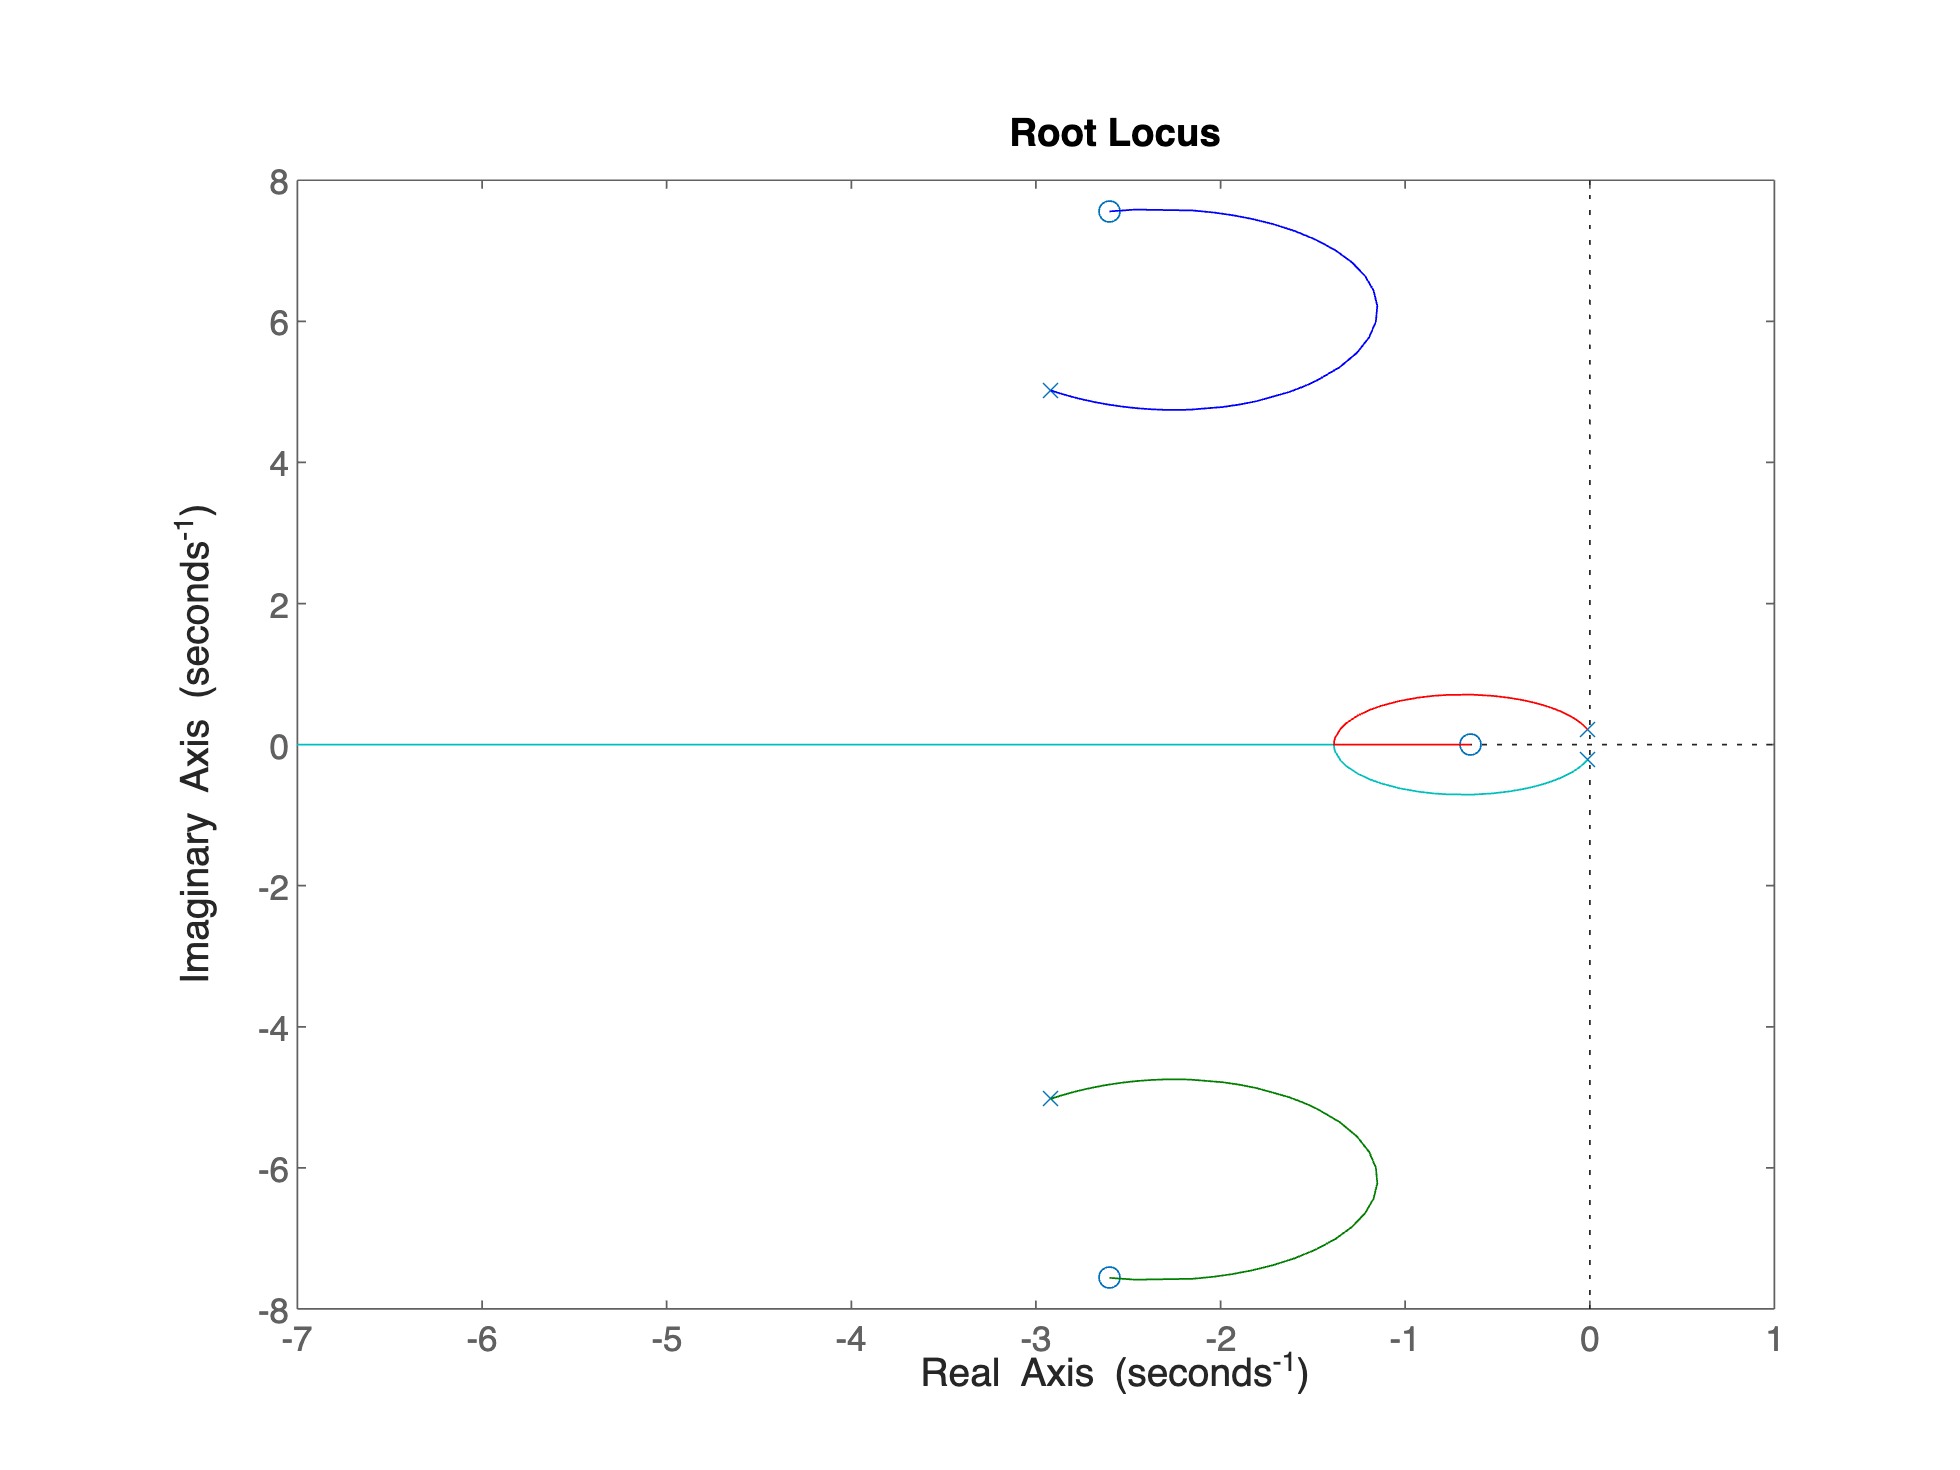

%Pour la vitesse en fonction de la poussé maximale
Couleur = ['r' 'g' 'b' 'm' 'y' 'c' 'k'];
Fig1 = figure;
Fig2 = figure;

%On choisi 
K_p = 1;
Kv = [1:1:10];

FT_Fraction_Vitesse = tf(Num2(1,:), Den2);

%Étape 2
Zero = roots(Num2(1,:));
Pole = roots(Den2);

%Étape 4
Asymptotes = [];
for k = 1:length(Pole)
    Asymptotes = [[Asymptotes] [((1+2*k)/(length(Pole)-length(Zero)))*pi]];
end

%Étape 8
Angle_P1 = 360 + 180 + (rad2deg(angle(Pole(1)-Zero(1)))+rad2deg(angle(Pole(1)-Zero(2)))+rad2deg(angle(Pole(1)-Zero(3)))) - (rad2deg(angle(Pole(1)-Pole(2)))+rad2deg(angle(Pole(1)-Pole(3)))+rad2deg(angle(Pole(1)-Pole(4))));
Angle_P3 = 180 + (rad2deg(angle(Pole(3)-Zero(1)))+rad2deg(angle(Pole(3)-Zero(2)))+rad2deg(angle(Pole(3)-Zero(3)))) - (rad2deg(angle(Pole(3)-Pole(2)))+rad2deg(angle(Pole(3)-Pole(1)))+rad2deg(angle(Pole(3)-Pole(4))));
Angle_Z1 = -360 + 180 - (rad2deg(angle(Zero(1)-Zero(2)))+rad2deg(angle(Zero(1)-Zero(3)))) + (rad2deg(angle(Zero(1)-Pole(1)))+rad2deg(angle(Zero(1)-Pole(2)))+rad2deg(angle(Zero(1)-Pole(3)))+rad2deg(angle(Zero(1)-Pole(4))));
Angle_Z3 = 180 - (rad2deg(angle(Zero(3)-Zero(1)))+rad2deg(angle(Zero(3)-Zero(2)))) + (rad2deg(angle(Zero(3)-Pole(1)))+rad2deg(angle(Zero(3)-Pole(2)))+rad2deg(angle(Zero(3)-Pole(3)))+rad2deg(angle(Zero(3)-Pole(4))));

p_Fraction_Vitesse = rlocus(FT_Fraction_Vitesse, K_p);

%On trace la locus
figure(Fig1)
rlocus(FT_Fraction_Vitesse)
hold on
%plot(real(p_Fraction_Vitesse), imag(p_Fraction_Vitesse), 'x', 'MarkerSize',10) 
hold on

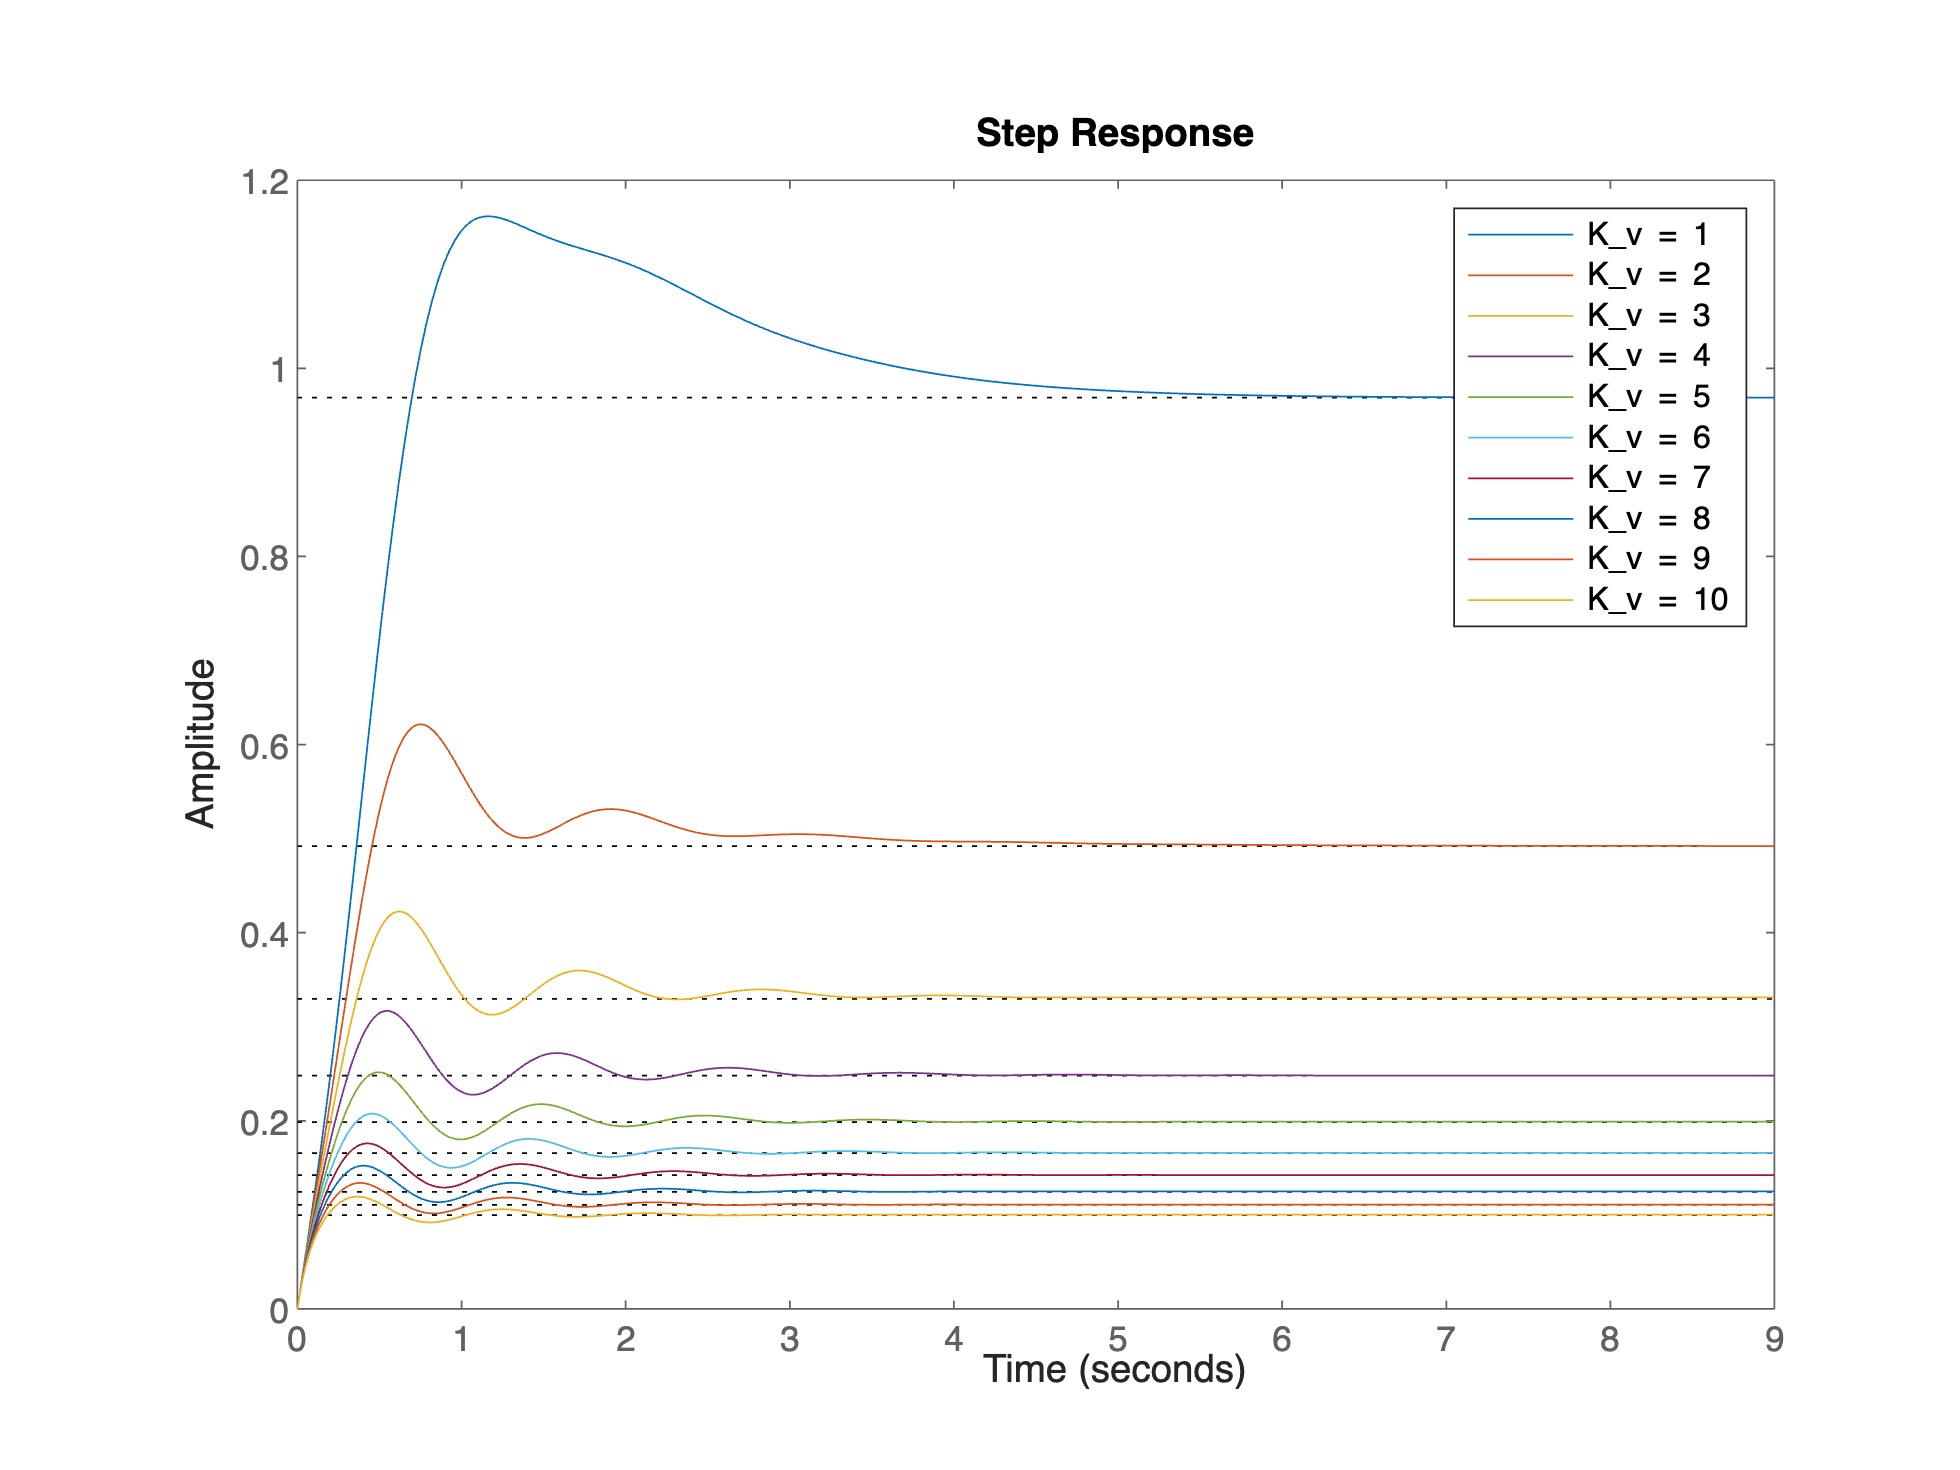


legende = [];
INFO = [];

%Faire Step response à plusieurs Kv
for i = 1:length(Kv)
    %On ressort la fonction de transfert importante
    FT_Fraction_Vitesse_Fermer = FT_Fraction_Vitesse/(1+Kv(i)*FT_Fraction_Vitesse);
    
    String = "K_v = " + num2str(Kv(i));
    legende = string([[legende], [String]]);
    
    INFO = [[INFO], [stepinfo(FT_Fraction_Vitesse_Fermer)]];

    figure(Fig2)
    step(FT_Fraction_Vitesse_Fermer)
    hold on
end
legend(legende)